Metoda bisekcji


Miejsce zerowe obliczone za pomocą fzero: 1.7397


    Iteration      x          f(x)    
    _________    ______    ___________

        1           5.5         4.2247
        2          3.25         2.9863
        3         2.125        0.97579
        4        1.5625       -0.48642
        5        1.8438        0.27519
        6        1.7031      -0.098514
        7        1.7734       0.090168
        8        1.7383     -0.0037228
        9        1.7559       0.043336
       10        1.7471       0.019835
       11        1.7427       0.008063
       12        1.7405      0.0021719
       13        1.7394    -0.00077505
       14        1.7399     0.00069851
       15        1.7397    -3.8239e-05
       16        1.7398     0.00033014
       17        1.7397     0.00014595
       18        1.7397     5.3858e-05
       19        1.7397     7.8093e-06
       20        1.7397    -1.5215e-05
       21        1.7397    -3.7028e-06


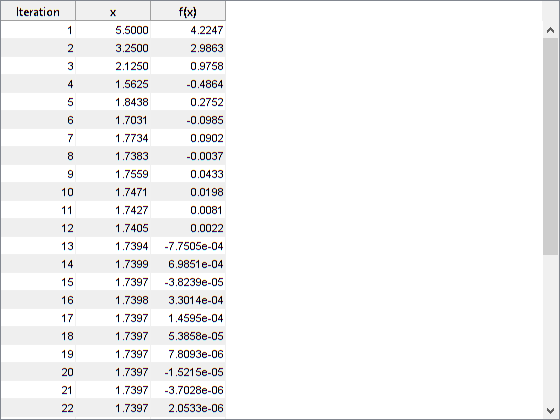

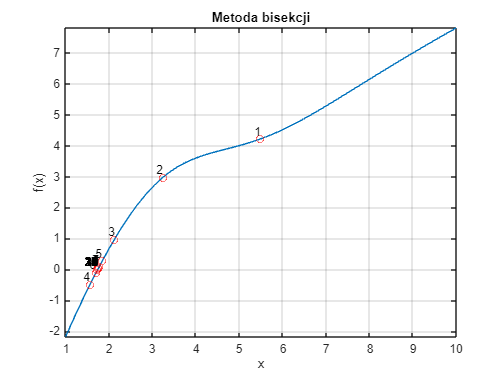

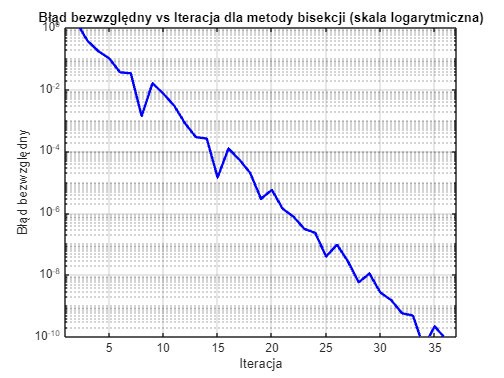

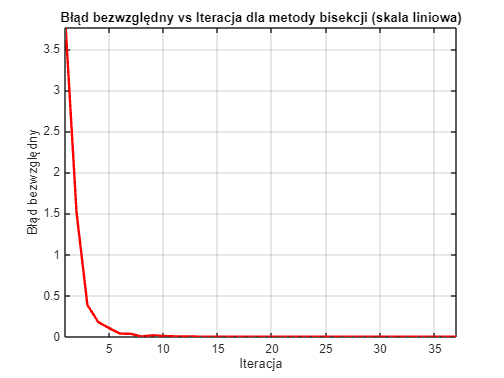

    Delta     Bisection iteration
    ______    ___________________

     1e-15            53         
     1e-14            50         
     1e-13            47         
     1e-12            44         
     1e-11            40         
     1e-10            37         
     1e-09            34         
     1e-08            30         
     1e-07            27         
     1e-06            24         
     1e-05            20         
    0.0001            17         
     0.001            14         
      0.01            10         
       0.1             7         



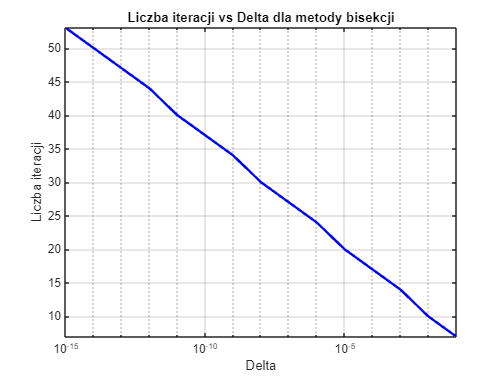

Metoda Mullera


Miejsce zerowe obliczone za pomocą fzero: 1.7397


    Iteration       x          f(x)    
    _________    _______    ___________

        1         2.3251         1.4315
        2        0.78674        -2.8917
        3         1.7341       -0.01499
        4         1.7397      7.176e-05
        5         1.7397    -8.2413e-10
        6         1.7397              0



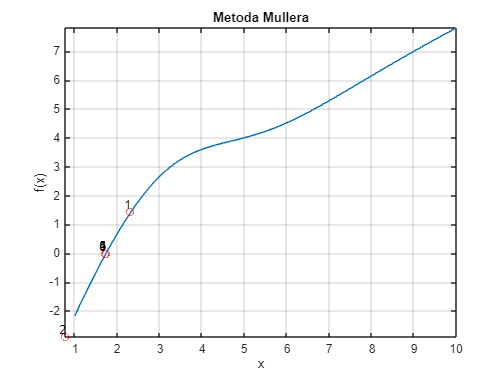

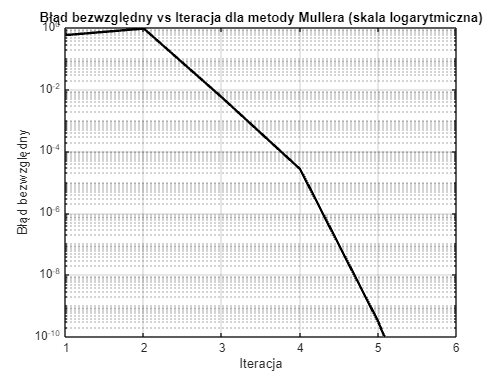

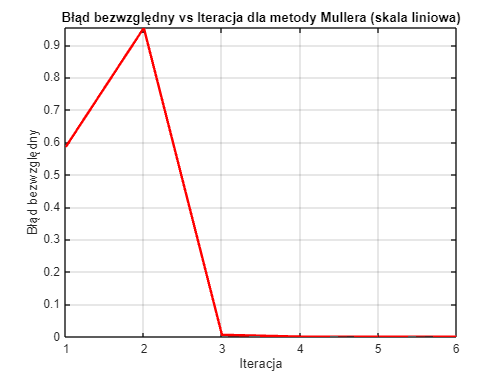

    Delta     Metoda Mullera iteracje
    ______    _______________________

     1e-15               6           
     1e-14               6           
     1e-13               6           
     1e-12               6           
     1e-11               6           
     1e-10               6           
     1e-09               5           
     1e-08               5           
     1e-07               5           
     1e-06               5           
     1e-05               5           
    0.0001               4           
     0.001               4           
      0.01               3           
       0.1               3           



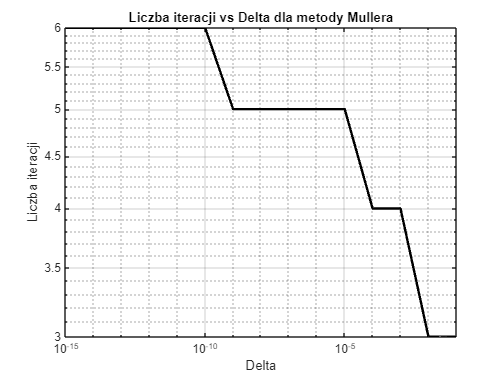

disp('Metoda Mullera')


% funkcja
f = @(x) 2 * exp(-((x/3-1).^2)).^2 + 5*sqrt(x) - 8;

% Funkcja metody Mullera
function [tableResults, errors_abs, num_iter] = muller_method(f, x_span, delta, x_ref)
    x1 = x_span(1);
    x2 = x_span(2);
    x3 = (x_span(1) + x_span(2)) / 2;
    k = 1;
    iter_data = [];

    % Warunek while: abs(x3 - x_ref) >= delta
    while abs(x3 - x_ref) >= delta
        % Obliczanie współczynników a i b
        A = [
            -(x3 - x2)^2, (x3 - x2);
            -(x3 - x1)^2, (x3 - x1)
        ];
        B = [
            f(x3) - f(x2);
            f(x3) - f(x1)
        ];
        coeff = A \ B;
        a = coeff(1);
        b = coeff(2);
        c = f(x3);

        % Wybór mianownika
        rad = sqrt(b^2 - 4*a*c);
        denom1 = b + rad;
        denom2 = b - rad;

        if abs(denom1) > abs(denom2)
            denom = denom1;
        else
            denom = denom2;
        end

        % Obliczanie następnego przybliżenia
        x_next = x3 - 2*c / denom;

        % Zapisanie iteracji
        iter_data = [iter_data; k, x_next, f(x_next)];
        
        if abs(x_next - x_ref) < delta
            break;
        end

        x1 = x2;
        x2 = x3;
        x3 = x_next;
        k = k + 1;
    end

    % Tworzenie tabeli wyników
    tableResults = array2table(iter_data, 'VariableNames', {'Iteration', 'x', 'f(x)'});
    errors_abs = abs(iter_data(:, 2) - x_ref); % Błąd bezwzględny względem x_ref
    num_iter = k;
end

x_span = [1, 10];
delta = 10^-10;

% Obliczenie miejsca zerowego za pomocą fzero jako punkt odniesienia
x_ref = fzero(f, x_span);
disp(['Miejsce zerowe obliczone za pomocą fzero: ', num2str(x_ref)]);

% Wywołanie funkcji muller_method i wyświetlenie wyników
[tableResults_muller, errors_abs_muller, num_iter_muller] = muller_method(f, x_span, delta, x_ref);
disp(tableResults_muller);

% Rysowanie wykresu metody Mullera
figure;
fplot(f, x_span);
xlabel('x');
ylabel('f(x)');
title('Metoda Mullera');
grid on;
axis tight; % Automatyczne dopasowanie osi
hold on;
for i = 1:height(tableResults_muller)
    plot(tableResults_muller.x(i), tableResults_muller.('f(x)')(i), 'ro');
    text(tableResults_muller.x(i), tableResults_muller.('f(x)')(i), num2str(i), 'VerticalAlignment', 'bottom', 'HorizontalAlignment', 'right');
end
hold off;

% Rysowanie wykresu błędów bezwzględnych dla metody Mullera
figure;
semilogy(1:length(errors_abs_muller), errors_abs_muller, 'k-', 'LineWidth', 2);
xlabel('Iteracja');
ylabel('Błąd bezwzględny');
title('Błąd bezwzględny vs Iteracja dla metody Mullera');
grid on;
xlim([1, length(errors_abs_muller)]); % Ustawienie zakresu osi X
ylim([10^-10, 1]); % Ustawienie zakresu osi Y
hold off;

% Zakres wartości delta
deltas = logspace(-15, -1, 15);

% Wyznaczenie liczby iteracji dla różnych wartości delta
num_iterations_muller = zeros(length(deltas), 1);
for j = 1:length(deltas)
    epsilon = deltas(j);
    [~, ~, num_iter] = muller_method(f, x_span, epsilon, x_ref);
    num_iterations_muller(j) = num_iter;
end

% Wyświetlenie wyników w tabeli
iterations_table_muller = table(deltas', num_iterations_muller, 'VariableNames', {'Delta', 'Metoda Mullera iteracje'});
disp(iterations_table_muller);

% Rysowanie wykresu liczby iteracji w zależności od delta dla metody Mullera
figure;
loglog(deltas, num_iterations_muller, 'k-', 'LineWidth', 2);
xlabel('Delta');
ylabel('Liczba iteracji');
title('Liczba iteracji vs Delta dla metody Mullera');
grid on;
axis tight; % Automatyczne dopasowanie osi
hold off;

